close all;
clear all;

%[success, variant_out, model_out, exitInfo]= sbiosteadystate(ans);
m = createEndometriosisModel2();

nva = struct with fields:
        ssIGF1: 15.6883
       ssIGFBP: 80
      ssIGFBPc: 120
       ssPAPPA: 0.2000
      ssPAPPA2: 0.0013
        rpIGF1: 128.7343
        raIGF1: 9.2500e-04
        trIGF1: 0.1670
       trIGFBP: 16
      trIGFBPc: 16
       trPAPPA: 100
      trPAPPA2: 100
         Kcat2: 1116
           Km2: 410
          Kcat: 3204
            Km: 1630
        FupmAB: 1
         ssARG: 100000
        ssARGi: 80000
          ssNO: 10
         trARG: 2
        trARGi: 1
          trNO: 10
         rpARG: 41.6000
         raARG: 9.2500e-04
        FupARG: 1
        ssPGE2: 1.1348
         ssEP3: 1.6670
      kpainEP3: 0.2821
    kelpainEP3: 1
      kinChOFF: 0.8000
        trPGE2: 0.1500
         trEP3: 12
           kon: 1
          koff: 5.8000
    exportFlag: 0
     kdegIGFBP: 0.0433
    kdegIGFBPc: 0.0433
     kdegPAPPA: 0.0069
    kdegPAPPA2: 0.0069
      kdegIGF1: 4.1506
       kinChON: 0.4000
     ksynIGFBP: 33.4447
    ksynIGFBPc: 5.5321
      ksynIGF1: 34.8031
   

r1 = 29.9789

r2 = 0.3335

ans =    SimBiology Parameter Array

   Index:    Name:       Value:      Units:
   1         kdegARGi    0.693147    1/hour


ans =    SimBiology Parameter Array

   Index:    Name:         Value:    Units:
   1         kelpainEP3    1         1/hour



% d1 = adddose(m,'testdose');
% d1.AmountUnits = 'nanomole';
% d1.TargetName = 'IGF1';
% d1.TimeUnits = 'hour';
% d1.StartTime = 40;
% d1.Amount = 1000;

cs = m.getconfigset;
cs.SolverOptions.AbsoluteTolerance = 1e-8;
cs.SolverOptions.RelativeTolerance = 1e-8;
set(cs,'StopTime',24*100);
set(cs,'TimeUnits','hour');

% this is only for debug purposes
% make all parameter variable so you would get their value as part of the
% simulation result
p=sbioselect(m,'type','parameter');
for i=1:length(p) p(i).Constant=0; end

R = sbiosimulate(m,cs);
m.addparameter('h',1, 'Units','hour');
NOx=0

NOx = 0

 m.addparameter('DeltaNO',NOx, 'Units','nanomolarity');
 on1 = addevent(m,'time/h>500','NO=NO+DeltaNO');
 off1 = addevent(m,'time/h>1000','NO=NO-DeltaNO');
%---------------------------------
IGF1x=180

IGF1x = 180

m.addparameter('DeltaIGF1',IGF1x, 'Units','nanomolarity');
on = addevent(m,'time/h>500','IGF1=IGF1+DeltaIGF1');
off = addevent(m,'time/h>1000','IGF1=IGF1-DeltaIGF1');
% %---------------------------------
%---------------------------------
EP3x=0

EP3x = 0

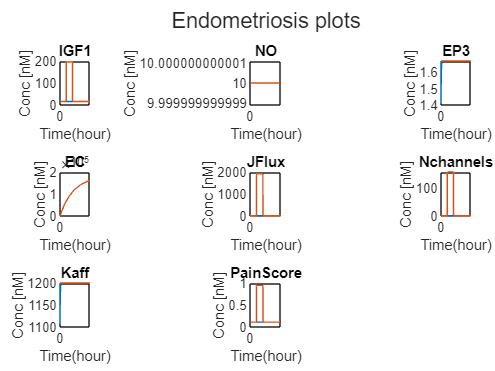

m.addparameter('DeltaEP3',EP3x, 'Units','nanomolarity');
on = addevent(m,'time/h>500','EP3=EP3+DeltaEP3');
off = addevent(m,'time/h>1000','EP3=EP3-DeltaEP3');
% %---------------------------------
dose = 100;
for jj = 1:length(dose)

IGF1 = sbioselect(m, 'Type', 'species', 'Name', 'IGF1');IGF1.BoundaryCondition = true;
% IGF1.InitialAmount = dose(jj);
% argi = sbioselect(m, 'Type', 'species', 'Name', 'Arginine_i');argi.BoundaryCondition = true;
% argi.InitialAmount = dose(jj);
NO = sbioselect(m, 'Type', 'species', 'Name', 'NO');NO.BoundaryCondition = true;
% NO.InitialAmount = 50;
EP3 = sbioselect(m, 'Type', 'species', 'Name', 'EP3');EP3.BoundaryCondition = true;
% EP3.InitialAmount = 10;
 
sd(jj) = sbiosimulate(m,cs);
%sdnew(jj) = resample(sd(jj),[1:16],'linear');
end


figure;
tl=tiledlayout("flow",'TileSpacing','compact','Padding','compact');
% Add layout title
title(tl,'Endometriosis plots');

%plotvars = {'IGF1','IGFBPc','PAPPA2','IGFBP','PAPPA','Arginine_i','NO','PGE2','EP3','EC','Ca','JFlux','PainFlux','PainF'};
plotvars = {'IGF1','NO','EP3','EC','JFlux','Nchannels','Kaff','PainScore'};
plotvars2 = {'IGF1','NO','EP3','EC','JFlux','Nchannels','Kaff', 'PainScore'};
for i=1:length(plotvars)
    nexttile;
    [t,x]=selectbyname(R,plotvars{i}); 
    plot(t,x);
    hold on;
    [t1,x1]=selectbyname(sd,plotvars2{i}); 
    plot(t1,x1);
    title(plotvars{i}); 
    xlabel(sprintf('Time(%s)',cs.TimeUnits));
    ylabel('Conc [nM]');
end